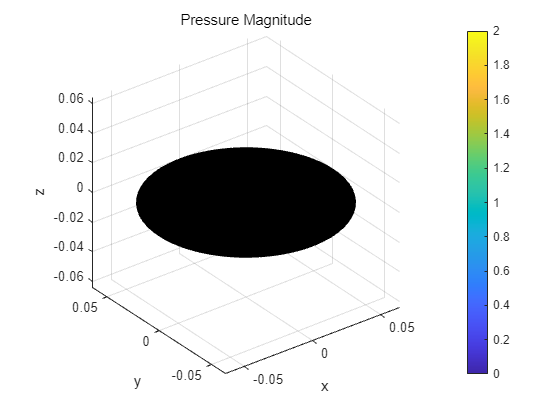

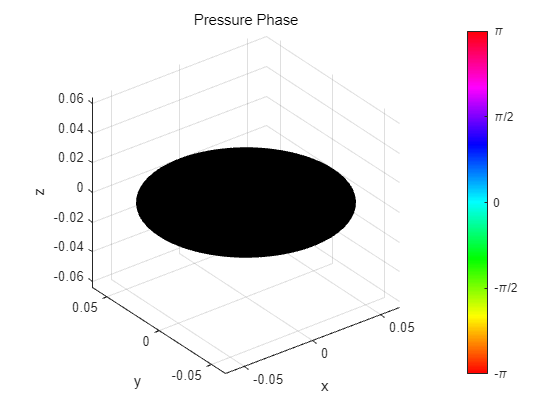

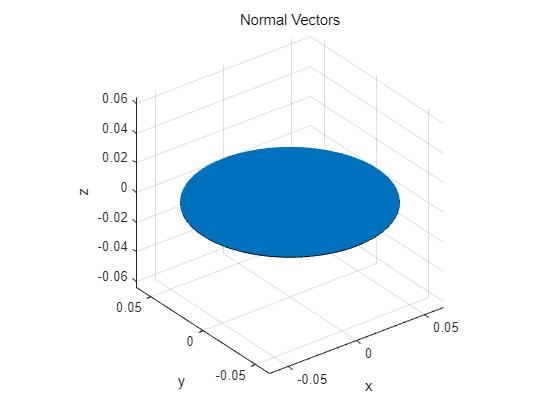

%% Transducer Design
transducer_info = [];

transducer_info.Frequency = 40000;
transducer_info.Pressure = 1;
transducer_info.Phase = 0;
transducer_info.Type = 'circle';
transducer_info.Radius = 0.064;
transducer_info.medium = 'air';

transducer_object = PFC_Make3DTransducer(transducer_info);

PFC_DrawTransducer3D(transducer_object, '-');


%% Frequency Domain
input_source = [];

input_source.Type = 'frequency';
input_source.reading_list = 40000; % [Hz]



%% Simulation Space
reading_pos_x = -80e-3 : 2e-3 : 80e-3;          % Simulation Area
reading_pos_y = -80e-3 : 2e-3 : 80e-3;          % Simulation Area
reading_pos_z = 0e-3 : 2e-3 : 600e-3;          % Simulation Area



%% Run Frequency Domain Simulation

% xz plane
[Pressure_dxyz] = ...
PFC_CalculatePressureField(...
transducer_object, input_source,...                 % tx setting
reading_pos_x, 0, reading_pos_z);

Started at 2024-08-16 12:05:44
Finished at 2024-08-16 12:07:48
Progressed time : 00:02:04


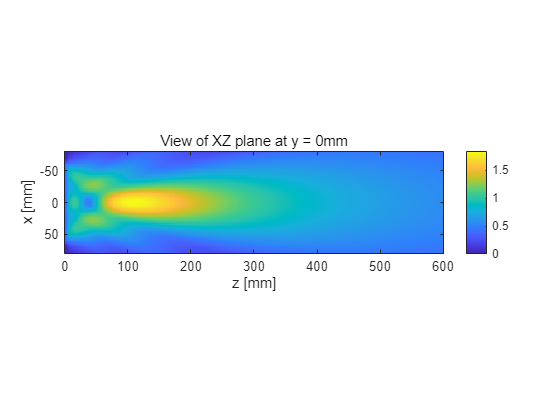


Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));

figure;imagesc(reading_pos_z.*1e3, reading_pos_x.*1e3, Pressure_dxyz_i);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top');
colorbar;
title('View of XZ plane at y = 0mm');
xlabel('z [mm]');
ylabel('x [mm]');

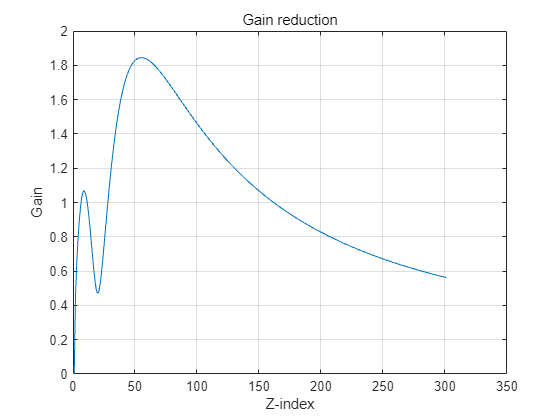

row_data = Pressure_dxyz_i(41, :);
plot(row_data);
xlabel('Z-index');
ylabel('Gain');
title('Gain reduction');
grid on;


% xy plane
[Pressure_dxyz] = ...
PFC_CalculatePressureField(...
transducer_object, input_source,...                 % tx setting
reading_pos_x, reading_pos_y, 0.128);

Started at 2024-08-16 12:04:35
Finished at 2024-08-16 12:05:10
Progressed time : 00:00:35


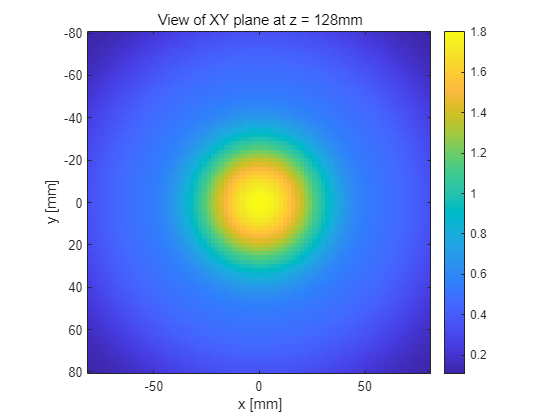


Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));

figure;imagesc(reading_pos_x.*1e3, reading_pos_y.*1e3, Pressure_dxyz_i);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top');
colorbar;
title('View of XY plane at z = 128mm');
xlabel('x [mm]');
ylabel('y [mm]');